## **Project 2: Motion Detection via Communication Signals**

## Name 1:  何家阳     SID 1:   12213023  

## Name 2:  唐小棋     SID 2:   12113050  

## Name 1:  朱家润     SID 1:   12210212  

## Name 2:  周纵一     SID 2:   12110303  

## ***1.Introduction***

#### After completing this project, I’m able to, 

#### 1. Mastery of Time-Domain Signal Processing:

####         （1）To do the digital down convert, we  need to multiply the original signal by a complex exponential signal. if we want to do a frequency  shift of 3Hz, that is, w=2pi*3, we need to multiply e^j2pi*3t . We can easily design a butterworth filter  with specific cut-off frequency and order by 'butter' function.

####           (2) Then we use 'filter' function to filter the  original signal. The corelation function can tell us the level of similarity of the two signals. 

####           (3)To caculate  it, we need to multiply the two signals and do the integration, which can be approximated by adding  up all of the magnitudes and multiple by delta t between two sampling points.

####  2.Frequency-Domain Signal Processing:

####          We can plot frequency spectrums to identify dominant frequencies in a signal. I have learned to design and validate low-pass filters using the 'butter' function and assess their effectiveness by checking if their magnitude is below -3dB at the cut-off frequency.

#### 3.Motion Detection via Communication Signals:

####          We understand how motion detection is applied in everyday life, especially through radar technology, which uses time and Doppler shifts to detect range and velocity.

### Theory: 

#### **Radar ： **

A method of detecting distant objects and determining their position, velocity, or other characteristics by analysis of very high frequency radio waves reflected from their surfaces. (Wikipedia)

#### Doppler shift:

Doppler shift is a change in the observed frequency of a wave occurring when the source and observer  are in motion relative to each other. 

Formula:

f: emitted frequency     f′ : received frequency

fD: doppler shift      c : velocity of waves in the medium 

vr: velocity of the receiver relative to the medium (positive if the receiver is moving  towards the source and negative if in the opposite direction) 

vs: velocity of the source relative to the medium (positive if the source is moving  away from the receiver and negative if in the opposite direction)\

**Active radars** keep emitting electromagnetic waves while working, which is easy to be located. Passive  radars keeps radio silence during target detection, which is difficult to locate or be interfered, so it is very  suitable for scenes with high requirements for concealment. Also, they don't require additional time or  frequency resources, so their cost and complexity is much lower than active ones. 

**The passive radar **will firstly receive a reference signal sent from a transmitter. Then, the receiver will also  receive the reflected signal (surveillance signal) scattered by the target. The target range and Doppler shift  can be estimated by calculating the time difference and frequency difference between the signals sampled  from the two channels. 

**Suppose the transmitted signal is x(t) :**

The reference signal is the transmitted signal after time delay and attenuation：

 The surveillance signal is the transmitted  signal after attenuation, time delay and  Doppler frequency offset：

TDOA (the Time Difference of Arrival between the  reference signal and the surveillance echo) :

while and is the total distance traveled by surveillance signal and reference signal. 

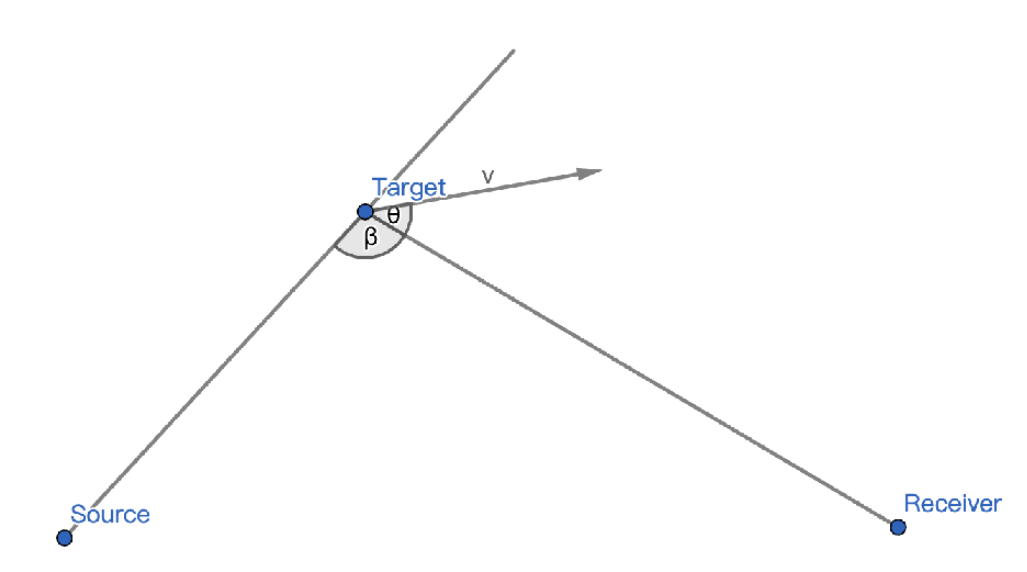

#### The frequency at source, target, receiver are fs, ft, fr respectively. In respect of source and target

#### 

#### In respect of target and receiver

Doppler shift fD is 

while is the wavelength of the signal at the source.

## Outdoor Experiment:

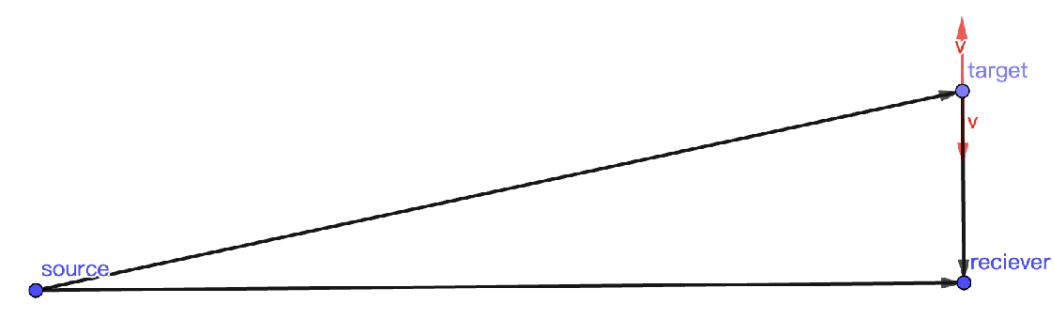

 the range between the moving object and the radar set can be caculated by:

Velocity (speed) is 

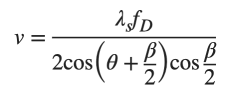

in our own situation, θ= 0,β≈ pi/2,thus:

Ambiguity function is a cross-corelative function, it can decide the relevance between two functions, thus  helping us to find out the most proper unknowns. We consider the unknowns τ, fD and time t0 as unknowns,  so the function is

Estimate Time Difference and Doppler shift (τ, fD):

To process the signals, we need to:

 1. read the original data 

2. do the digital down convert 

3. low-pass filtering 

4. ambiguity function process 

5. plot the spectrum 

That is to do the frequency shift to make the center of the frequency domain zero, then filter out the  unwanted frequencies, then estimate the  τ, fD  using Cor(τ,fD,t0) at different time periods, then plot the  range-doppler spectrum out, and find  plot the time-doppler spectrum and  analyze the motion of the object. 

## *2.Results & Analysis：*

## *(一)Task1*

#### *（1）Analysis：*

     For the reference signal and the surveillance signal, draw their time domain waveforms and their frequency  domain waveforms. 

    Firstly, we set up a low-pass filter whose cut-off frequency is 9*10^6 Hz

     We see from the following figure that when frequency is larger then 9MHz, the magnitude is lower than -3dB.  Therefore the lowpass filter is valid. 

####     CODE:lowfil.m

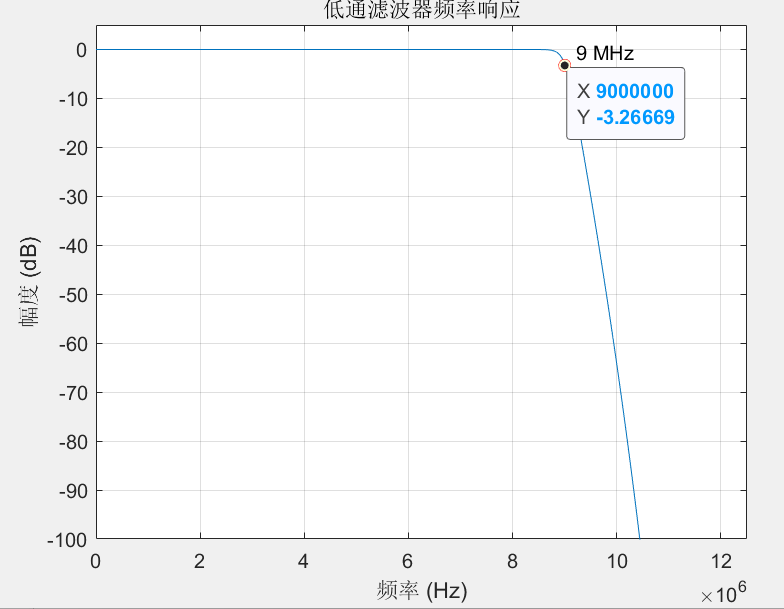

## (3)**结果**

    Next, we do the digital down convert, low-pass filtering and plot them. Since there are too many signals, we  randomly choose 1 signal from the 20 signals to be plotted

####    CODE:ddc.mlx

### (1)原信号时域、频域图像：

           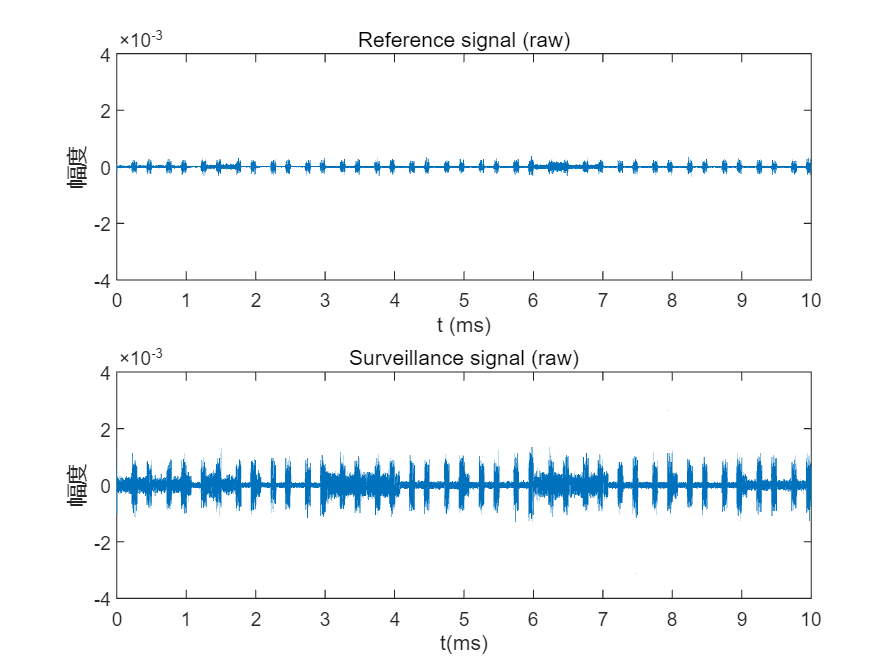    

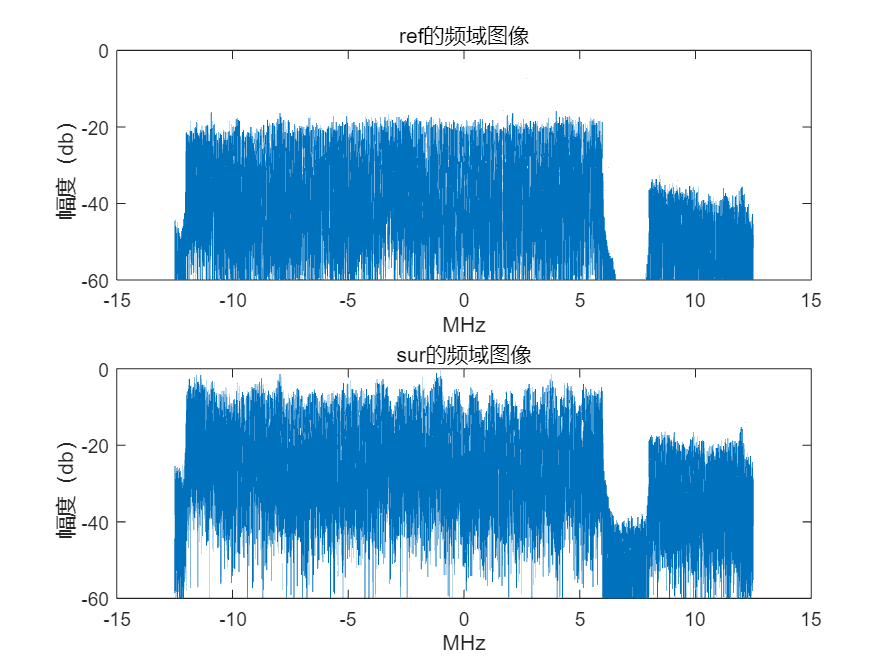

### （2）频移后：

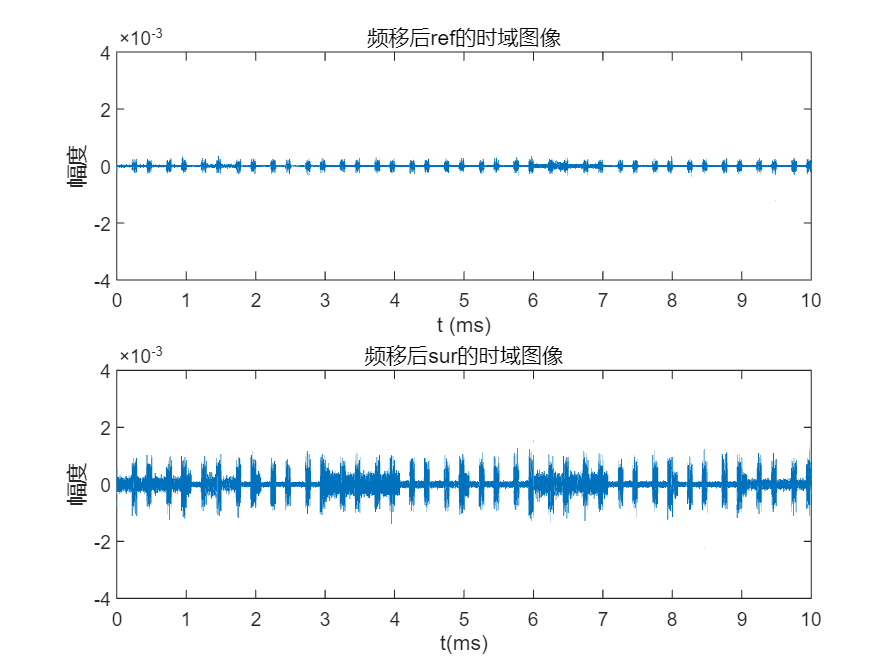

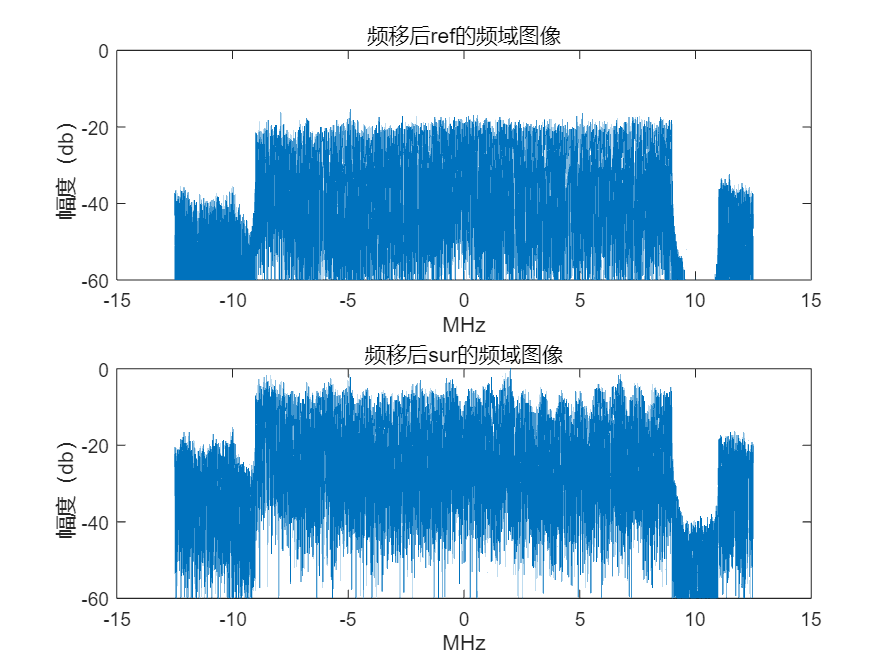

### （3）低通滤波后：

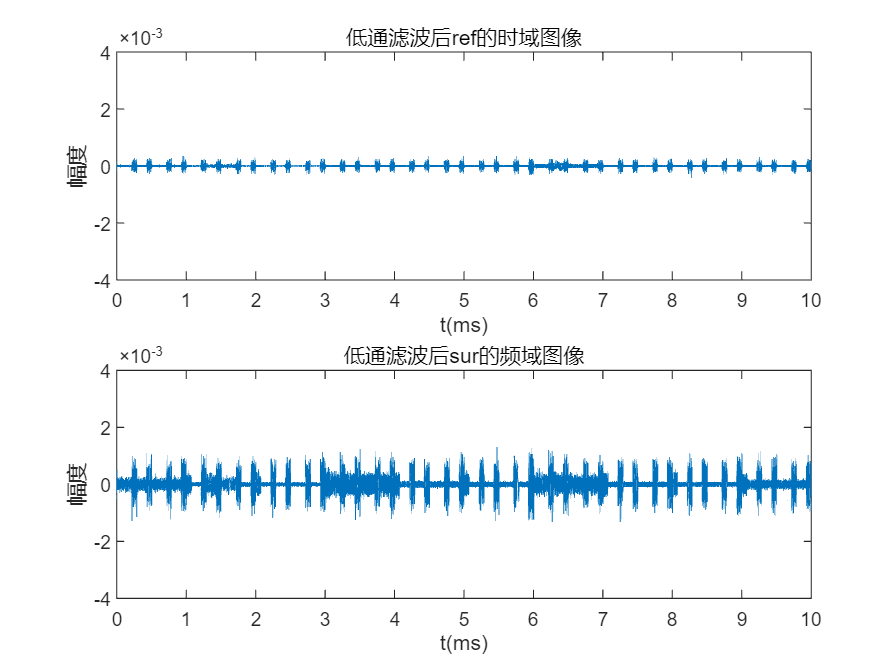

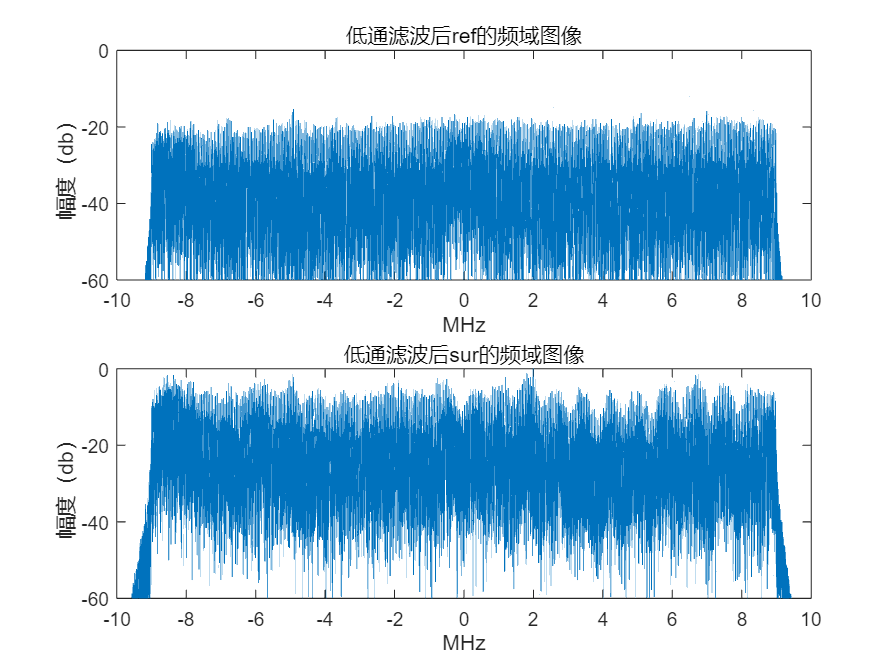

As above,the result is satisfactory.

### （4）结论

After digital down convert, the signal 2110-2130MHz (20M bandwidth) is converted to the frequency centered on 0 Hz.

## ***（二）Task 2:***

### Plot the Range-Doppler spectrum of the signal located at 0-0.5s, 2-2.5s, 5-5.5s and 7-7.5s.

We set up some loops to caculate different Cor(τ,fD,t0).We plot the range-doppler spectrums, and try to find the maximum value of at different . That  is, we consider as a constant while considering as variables. We listed related range and doppler  frequency at the titles of each picture. Following are range-doppler spectrums at 0-0.5s, 2-2.5s, 5-5.5s and  7-7.5s. 

####     Code:Range Doppler.mlx

## **结果**

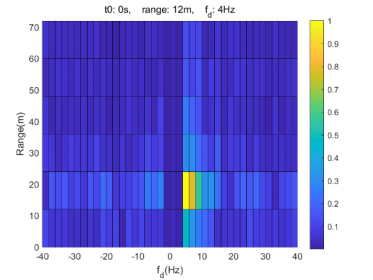

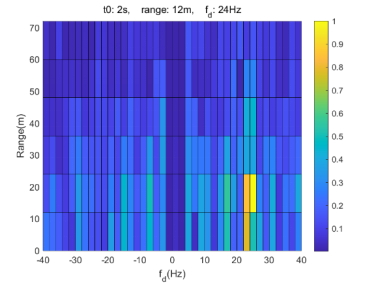

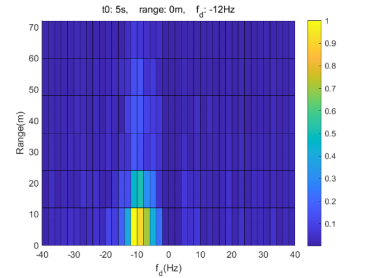

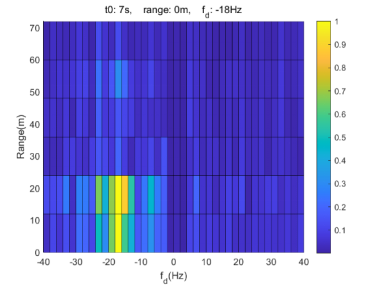

### *（三）TASK2拓展*

### 1.并行乘法加速

**思路：基础方法中，我们使用了一个for循环串行计算特定tau和fd下的模糊函数结果；然而，该计算可以并行实现，通过将该for循环改写为矩阵点乘的形式，充分调度CPU资源，加速运算。**

#### CODE：Range Doppler Quicker1.mlx

计算结果和图像结果与基础方法一致

优化前：

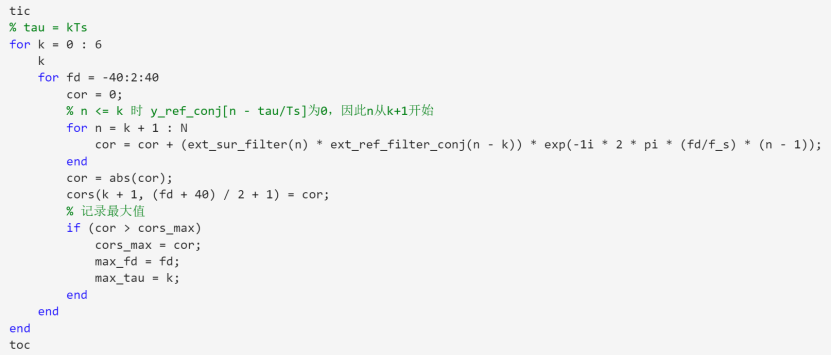

三次测量时间[434.42 421.59 421.49]，平均值425.83s

优化后：

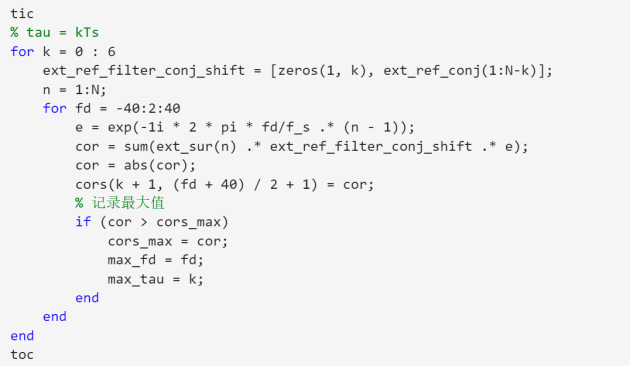

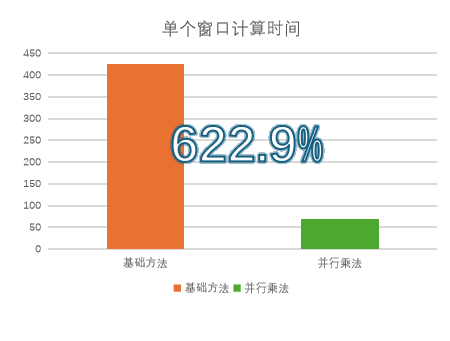

三次测量时间[69.05 67.98 68.05]，平均值68.36s，较优化前加速622.92%

### 2.随机采样加速

**思路：通过一定数量的随机采样点，估计模糊函数计算结果，加速运算过程。该方法可能导致估计结果与实际结果不符，因此需要测试准确率；实际应用中，根据实际需要的运算速度选择合适的采样点个数，达到性能与准确率的平衡。**

CODE：Range Doppler Quicker2.mlx

计算结果：cors_Quicker2/采样点个数

图像结果：imgs_Quicker2/采样点个数

采样计算过程：

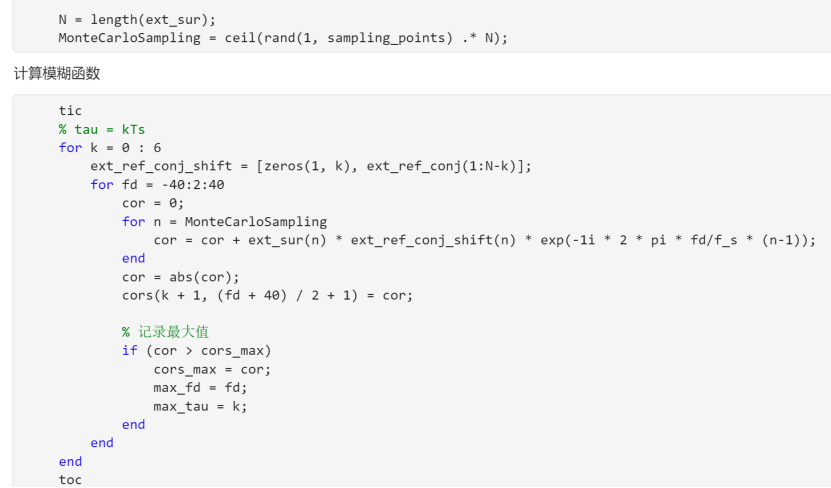

### 结果

全采样（即基础方法-作为对照组）

测量时间：425.83s

命中率与相似度均为100%

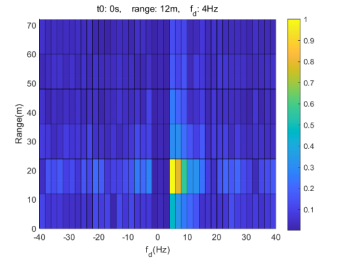

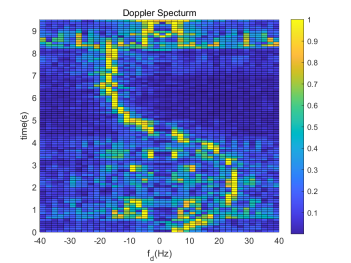

采样点个数（sampling_points）取值：100

测量时间：0.76s

命中率：Range = 32.3%，Freqd = 10.4%

相似度：Range = 71.4%，Freqd = 78.2%

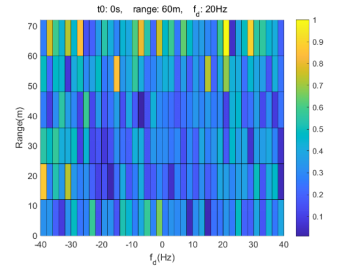

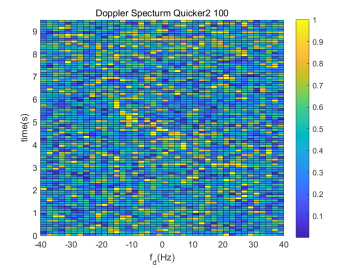

采样点个数（sampling_points）取值：1000

测量时间：0.68s

命中率：Range = 63.5%，Freqd = 57.3%

相似度：Range = 88.5%，Freqd = 90.4%

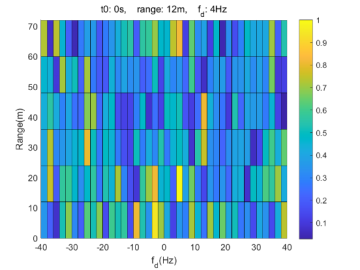

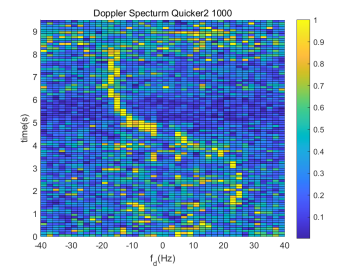

采样点个数（sampling_points）取值：10000

测量时间：1.59s

命中率：Range = 85.4%，Freqd = 78.1%

相似度：Range = 94.7%，Freqd = 96.6%

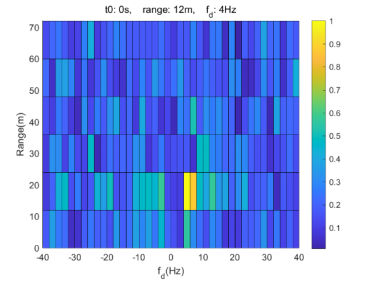

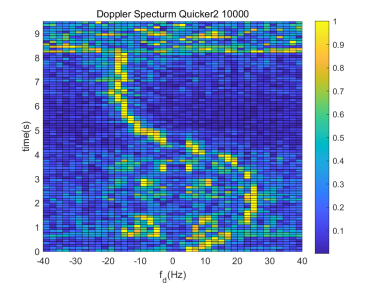

采样点个数（sampling_points）取值：100000

测量时间：9.62s

准确率：Range = 93.8%，Freqd = 89.5%

相似度：Range = 98.5%，Freqd = 97.9%

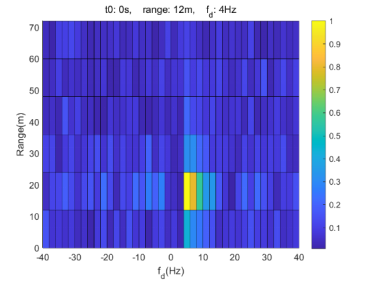

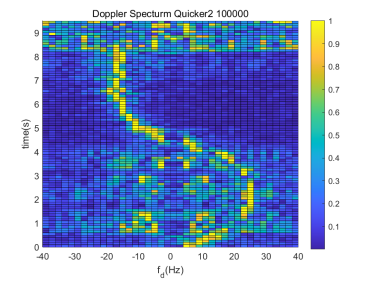

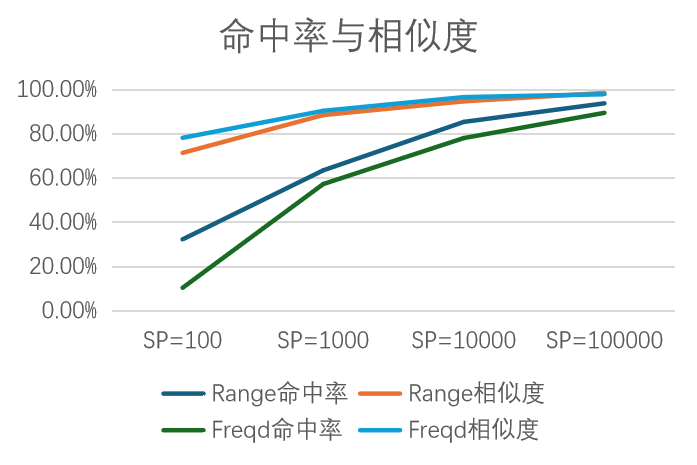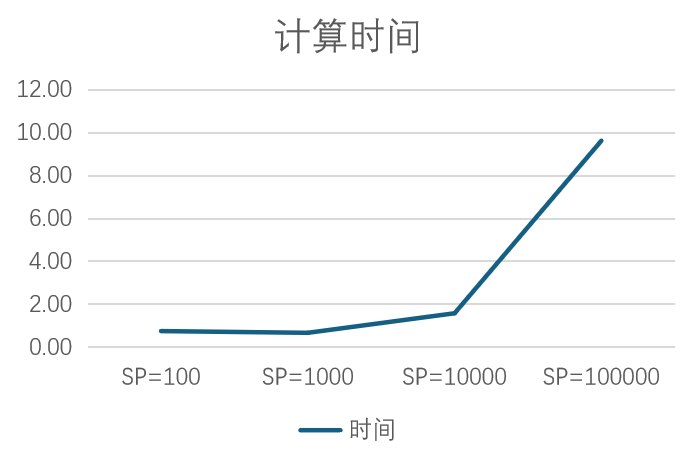

#### *分析:*

***可以看见，随着采样点个数的提高，计算结果和图像逐步逼近正确结果***

***（作为一个工程问题，舍弃部分精度以获取更高速度是十分合理的）***

### 3.并行随机采样

**思路：综合前两种方法的优点，在随机采样的基础上使用并行计算，加速计算**

**计算结果和图像结果与Bonus方法2一致**

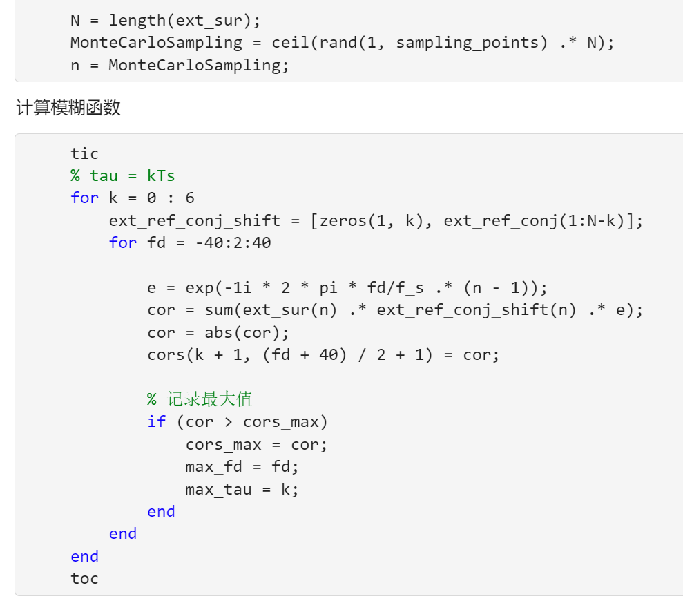

**CODE：**CODE：Range Doppler Quicker3.mlx

RESULT:

采样点个数（sampling_points）取值为100000时，三次测量平均为2.05s，较Bonus方法2加速469%

## *（四）Task3*

** Plot the Time-Doppler spectrum with coherent integration time (CIT) equal to 0.5s.  Time range is 0-9.5s**

1.定义函数g(d,t)=max | Cor(c,d,t)|,并将其向量化为g（t）

2.归一化

3.绘制以时间t为自变量的t - fd谱

Code: Time Doppler

### (4)结果：

时间窗口t = 0.5s	

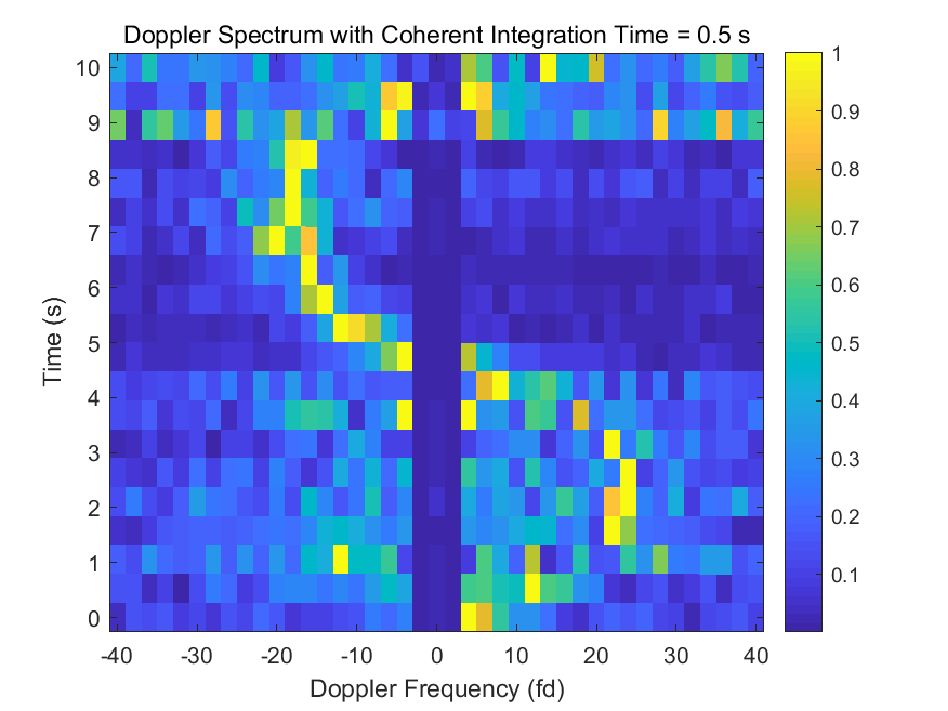

时间窗口t=0.1s

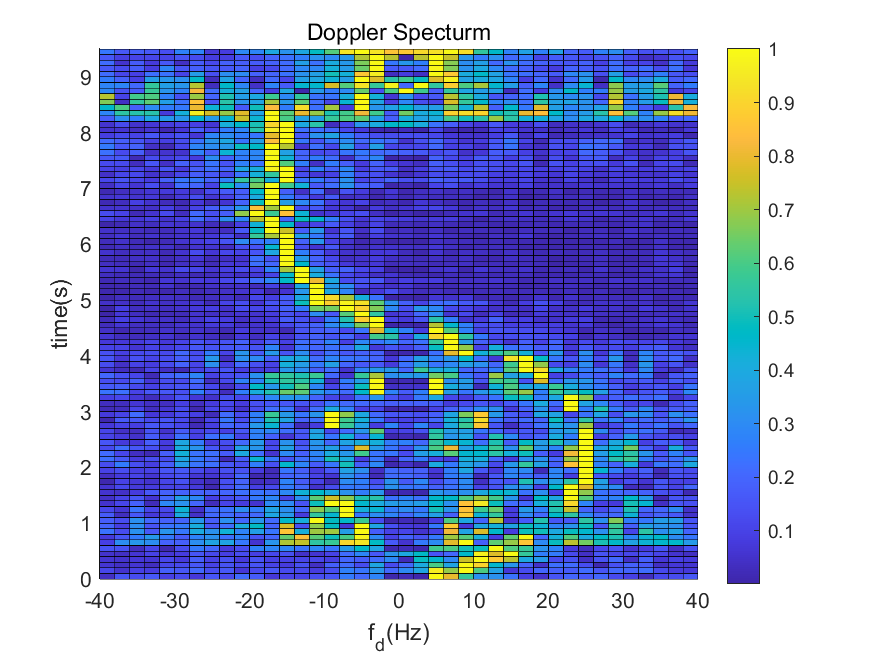

## *结果分析：*

The Doppler spectrum obtained at t=0.1s can more accurately display time variations and show more detailed images, whereas the image at t=0.5s is relatively coarser. If high precision in time measurement or the study of rapidly changing phenomena is required, the image on the right might be more suitable. However, if the time precision requirements are not as high, the image on the left may be sufficient to meet the needs.

From the range-doppler spectrums, we can know that the student is moving mainly in the range of 0～24  meters. We know the speed of the student can be caculated by , but we don't know the frequency   . So, we can only analysis qualitatively accroding to the time-doppler spectrum. The  student started from zero velocity, then moved towards the radars, and then turned back at about 4.7  seconds later and moved away from the radars

## **Experience:**

**     1.在本次project实验中，我们学会并掌握了：基于通信信号的运动检测，掌握了时域和频域下的处理方法，以及通信信号的运动检测技术在生活中的应用。**

**    2.在本次仿真的过程中，我们遇到了计算时间太缓慢的问题，所以自主探究了并行计算、随机采样以及二者结合的方式来加快实验效率；同时，我们遇到了一些做图结果与预期不一致，添加网格困难的问题，经过小组合作纠正，我们顺利克服困难完成了任务。**

**    3.加分项：我们一共实现了3个加分项，主要是基于运行时间缓慢的问题给出了并行计算加速、随机采样加速、二者同时使用的方法，显著提升了实验效率，并画出了实验图像证明正确性。**

## **贡献百分比：各 25%**

## **Name 1****:  何家阳     ****SID 1:****   12213023  滤波器验证，实验报告整理**

## **Name 2****:  唐小棋     ****SID 2:****   12113050   Task3**

## **Name 1****:  朱家润     ****SID 1:****   12210212  Task2及bonus**

## **Name 2****:  周纵一     ****SID 2:****   12110303  Task1**

## **Score:**

### **何家阳：100，唐小棋：100，朱家润：100，周纵一：100；**

## CODE

lowfil.m

% 参数设置
order = 20;
cutoff = 9 * 10^6; % 截止频率
f_s = 25000000;

% 设计低通滤波器
[b, a] = butter(order, cutoff / (f_s / 2), 'low');

% 计算频率响应
[H, f] = freqz(b, a, 1024, f_s);

% 绘制频率响应
figure;
plot(f, 20*log10(abs(H)));
title('低通滤波器频率响应');
xlabel('频率 (Hz)');
ylabel('幅度 (dB)');
grid on;
xlim([0 f_s/2]);
ylim([-100 5]);

% 标注截止频率
hold on;
cutoff_index = find(f >= cutoff, 1);
plot(cutoff, 20*log10(abs(H(cutoff_index))), 'ro');
text(cutoff, 20*log10(abs(H(cutoff_index))), ['  ' num2str(cutoff/10^6) ' MHz'], 'VerticalAlignment', 'bottom');
hold off;


#### ddc.mlx

时间范围

clc, clear,close all;
load(sprintf('data/data_%d.mat',1));
t = 0:1/f_s:0.01-1/f_s;  

 提取0.01秒的数据

ext_ref = seq_ref(1:0.01*f_s);
ext_sur = seq_sur(1:0.01*f_s);


绘制原信号的时域图像

 ext_ref (原信号)的时域图像

figure;
subplot(2, 1, 1);
plot(t*10^3,ext_ref);
title('Reference signal (raw)');
xlabel('t (ms)');
ylabel('幅度');
ylim([-4*10^-3 4*10^-3]);

 ext_sur（原信号）的时域图像

subplot(2, 1, 2);
plot(t*10^3, ext_sur);
title('Surveillance signal (raw)');
xlabel('t(ms)');
ylabel('幅度');
ylim([-4*10^-3 4*10^-3]);

绘制原信号的频域函数

fft_ref = fft(ext_ref);
fft_sur = fft(ext_sur);
N = length(fft(ext_ref));
%频谱横坐标
f1 = (-(N-1)/2:(N-1)/2)*f_s/(N*10^6);
%频谱纵坐标
magnitude_ref=20 * log10(abs(fft_ref));
magnitude_sur=20 * log10(abs(fft_sur));
fftshift_magnitude_ref = fftshift(20 * log10(abs(fft_ref)));
fftshift_magnitude_sur = fftshift(20 * log10(abs(fft_sur)));
figure;
subplot(2,1,1)
plot(f1,fftshift_magnitude_ref);
ylim([-60 0]);
title('ref的频域图像');
xlabel('MHz');
ylabel('幅度（db）');

subplot(2,1,2)
plot(f1,fftshift_magnitude_sur);
ylim([-60 0]);
title('sur的频域图像');
xlabel('MHz');
ylabel('幅度（db）');
f_fftshift = (-N/2:N/2-1) * f_s/N;
f2 = f_fftshift + 3*10^6;

%频移
f_ddc=3e6;
ref_shift=ext_ref.*exp(1i*2*pi*f_ddc*(0:1:length(ext_ref)-1)/f_s);
sur_shift=ext_sur.*exp(1i*2*pi*f_ddc*(0:1:length(ext_ref)-1)/f_s);

% 绘制频移后的时域图像
figure;
subplot(2, 1, 1);
plot(t*10^3,ref_shift);
title('频移后ref的时域图像');
xlabel('t (ms)');
ylabel('幅度');
ylim([-4*10^-3 4*10^-3]);

 ext_sur（原信号）的时域图像

subplot(2, 1, 2);
plot(t*10^3, sur_shift);
title('频移后sur的时域图像');
xlabel('t(ms)');
ylabel('幅度');
ylim([-4*10^-3 4*10^-3]);


fft_ref = fft(ref_shift);
fft_sur = fft(sur_shift);
N = length(fft(ext_ref));
%频谱横坐标
f1 = (-(N-1)/2:(N-1)/2)*f_s/(N*10^6);
%频谱纵坐标
magnitude_ref=20 * log10(abs(fft_ref));
magnitude_sur=20 * log10(abs(fft_sur));
fftshift_magnitude_ref = fftshift(20 * log10(abs(fft_ref)));
fftshift_magnitude_sur = fftshift(20 * log10(abs(fft_sur)));
figure;
subplot(2,1,1)
plot(f1,fftshift_magnitude_ref);
ylim([-60 0]);
title('频移后ref的频域图像');
xlabel('MHz');
ylabel('幅度（db）');

subplot(2,1,2)
plot(f1,fftshift_magnitude_sur);
ylim([-60 0]);
title('频移后sur的频域图像');
xlabel('MHz');
ylabel('幅度（db）');

%画出低通滤波后的时域图像
%设计lowpass filter
[b, a] = butter(20, 9*10^6/(f_s/2),'low');

%低通滤波
ref_filter = filter(b,a,ref_shift);
sur_filter = filter(b,a,sur_shift);

figure;
subplot(2,1,1)
plot(t*10^3,ref_filter);
xlabel('t(ms)');
ylabel('幅度');
ylim([-4*10^-3 4*10^-3]);
title('低通滤波后ref的时域图像');
subplot(2,1,2)
plot(t*10^3,sur_filter);
xlabel('t(ms)');
ylabel('幅度');
ylim([-4*10^-3 4*10^-3]);
title('低通滤波后sur的频域图像');

% 画出经过低通滤波的频谱图像
fft_ref = fft(ref_filter);
fft_sur = fft(sur_filter);
N = length(fft(ext_ref));
%频谱横坐标
f1 = (-(N-1)/2:(N-1)/2)*f_s/(N*10^6);
%频谱纵坐标
magnitude_ref=20 * log10(abs(fft_ref));
magnitude_sur=20 * log10(abs(fft_sur));
fftshift_magnitude_ref = fftshift(20 * log10(abs(fft_ref)));
fftshift_magnitude_sur = fftshift(20 * log10(abs(fft_sur)));
figure;
subplot(2,1,1)
plot(f1,fftshift_magnitude_ref);
ylim([-60 0]);
title('低通滤波后ref的频域图像');
xlabel('MHz');
ylabel('幅度（db）');

subplot(2,1,2)
plot(f1,fftshift_magnitude_sur);
ylim([-60 0]);
title('低通滤波后sur的频域图像');
xlabel('MHz');
ylabel('幅度（db）');


Range Doppler.mlx

读取所有数据，经过DDC与LPF后拼接至ref与sur

ref和sur中包含了[0, 10]s的所有完整数据，是为了方便task3的滑动窗口的计算

如果仅考虑task2计算，则无需拼接，只要在计算每个时间区间时读取对应数据即可

clc, clear,close all;

ref = zeros(1, 250000000);
sur = zeros(1, 250000000);
load(sprintf('data/data_%d.mat',1));

% 设计低通滤波器
[b, a] = butter(20, 9*10^6/(f_s/2),'low');

% 读取并拼接所有的文件
for idx = 1:20
    left = (idx - 1) * (12500000) + 1;
    right = idx * 12500000;
    load(sprintf('data/data_%d.mat',idx));

    % 频移
    f_ddc=3e6;
    ref_shift=seq_ref.*exp(1i*2*pi*f_ddc*(0:1:length(seq_ref)-1)/f_s);
    sur_shift=seq_sur.*exp(1i*2*pi*f_ddc*(0:1:length(seq_sur)-1)/f_s);

    % 低通滤波
    ref_filter = filter(b,a,ref_shift);
    sur_filter = filter(b,a,sur_shift);

    ref(left:right) = ref_filter;
    sur(left:right) = sur_filter;
end

对选定区间进行计算

t_interval = 0.5;
idxs = [1, 5, 11, 15]; % 取t0 = [0.0, 2.0, 5.0, 7.0]进行计算并绘图（实际上，imgs文件夹中内容由Range Doppler Quicker1计算得到，保存了所有时间区间的图像）
for index = idxs
index
ext_ref = ref((index - 1) * t_interval * f_s + 1 : index * t_interval * f_s);
ext_sur = sur((index - 1) * t_interval * f_s + 1 : index * t_interval * f_s);

% 取ref共轭
ext_ref_filter_conj = conj(ext_ref_filter);

% 结果保存在cors中（实际上，cors文件夹中的内容由Range Doppler Quicker1计算得到，保存了所有时间区间的计算结果）
cors = zeros(7, 41);
cors_max = 0;
max_fd = -1;
max_tau = -1;

N = length(ext_sur_filter);

计算模糊函数

tic
% tau = kTs
for k = 0 : 6
    for fd = -40:2:40
        cor = 0;
        % n <= k 时 y_ref_conj[n - tau/Ts]为0，因此n从k+1开始
        for n = k + 1 : N
            cor = cor + (ext_sur_filter(n) * ext_ref_filter_conj(n - k)) * exp(-1i * 2 * pi * (fd/f_s) * (n - 1));
        end
        cor = abs(cor);
        cors(k + 1, (fd + 40) / 2 + 1) = cor;
        % 记录最大值
        if (cor > cors_max) 
            cors_max = cor;
            max_fd = fd;
            max_tau = k;
        end
    end
end
toc

画图

% range = 0:12:72;
% freqd = -40:2:40;
% [F,R]=meshgrid(freqd,range);
% surf(F,R,cors / cors_max);
% view(0,90);
% ylim([0 72]);
% xlim([-40 40]);
% xlabel("f_{d}(Hz)");
% ylabel("Range(m)");
% title("t0: " + (index - 1) * 0.5 + "s, range: " + max_tau * 12 + "m, f_{d}: " + max_fd + "Hz");
% colorbar
% filename = "imgs/Range-Doppler-" + ((index - 1) * 5 + 1) + ".png";
% saveas(gcf, filename, 'png');

保存数据

% save("cors/cors" + index + ".mat", "cors");
end

`Range Doppler Quicker1.mlx`

读取所有数据，经过DDC与LPF后拼接至ref与sur

ref和sur中包含了[0, 10]s的所有完整数据，是为了方便task3的滑动窗口的计算

如果仅考虑task2计算，则无需拼接，只要在计算每个时间区间时读取对应数据即可

clc, clear,close all;

ref = zeros(1, 250000000);
sur = zeros(1, 250000000);
load(sprintf('data/data_%d.mat',1));

% 设计低通滤波器
[b, a] = butter(20, 9*10^6/(f_s/2),'low');

% 读取所有的文件，将下面改成for idx = 1:20
for idx = 1:20
    left = (idx - 1) * (12500000) + 1;
    right = idx * 12500000;
    load(sprintf('data/data_%d.mat',idx));

    % 频移（DDC）
    f_ddc=3e6;
    ref_shift=seq_ref.*exp(1i*2*pi*f_ddc*(0:1:length(seq_ref)-1)/f_s);
    sur_shift=seq_sur.*exp(1i*2*pi*f_ddc*(0:1:length(seq_sur)-1)/f_s);

    % 低通滤波（LPF）
    ref_filter = filter(b,a,ref_shift);
    sur_filter = filter(b,a,sur_shift);

    ref(left:right) = ref_filter;
    sur(left:right) = sur_filter;
end

对每个区间进行计算

t_interval = 0.5;
t0s = 0:0.1:9.5; % 取t0 = [0.0, 2.0, 5.0, 7.0]进行计算并绘图（实际上，imgs文件夹中保存了所有时间区间的图像）
for t0 = t0s
    t0
    ext_ref = ref(t0 * f_s + 1 : (t0 + t_interval) * f_s);
    ext_sur = sur(t0 * f_s + 1 : (t0 + t_interval) * f_s);
    
    % 取ref共轭
    ext_ref_conj = conj(ext_ref);
    
    % 结果保存在cors中
    cors = zeros(7, 41);
    cors_max = 0;
    max_fd = -1;
    max_tau = -1;
    
    N = length(ext_sur);

计算模糊函数

    tic
    % tau = kTs
    for k = 0 : 6
        ext_ref_conj_shift = [zeros(1, k), ext_ref_conj(1:N-k)];
        n = 1:N;
        for fd = -40:2:40
            e = exp(-1i * 2 * pi * fd/f_s .* (n - 1));
            cor = sum(ext_sur(n) .* ext_ref_conj_shift .* e);
            cor = abs(cor);
            cors(k + 1, (fd + 40) / 2 + 1) = cor;
            % 记录最大值
            if (cor > cors_max) 
                cors_max = cor;
                max_fd = fd;
                max_tau = k;
            end
        end
    end
    toc

画图并保存

    range = 0:12:72;
    freqd = -40:2:40;
    [F,R]=meshgrid(freqd,range);
    surf(F,R,cors / cors_max);
    view(0,90);
    ylim([0 72]);
    xlim([-40 40]);
    xlabel("f_{d}(Hz)");
    ylabel("Range(m)");
    title("t0: " + t0 + "s,    range: " + max_tau * 12 + "m,    f_{d}: " + max_fd + "Hz");
    colorbar
    filename = "imgs_Quicker1/Range-Doppler" + (t0 / 0.1 + 1) + ".png";
    saveas(gcf, filename, 'png');

保存数据

    save("cors/cors" + (t0 / 0.1 + 1) + ".mat", "cors");
end

`Range Doppler Quicker2.mlx`

读取所有数据，经过DDC与LPF后拼接至ref与sur

ref和sur中包含了[0, 10]s的所有完整数据，是为了方便task3的滑动窗口的计算

如果仅考虑task2计算，则无需拼接，只要在计算每个时间区间时读取对应数据即可

clc, clear,close all;

ref = zeros(1, 250000000);
sur = zeros(1, 250000000);
load(sprintf('data/data_%d.mat',1));

% 设计低通滤波器
[b, a] = butter(20, 9*10^6/(f_s/2),'low');

% 读取所有的文件，将下面改成for idx = 1:20
for idx = 1:20
    left = (idx - 1) * (12500000) + 1;
    right = idx * 12500000;
    load(sprintf('data/data_%d.mat',idx));

    % 频移（DDC）
    f_ddc=3e6;
    ref_shift=seq_ref.*exp(1i*2*pi*f_ddc*(0:1:length(seq_ref)-1)/f_s);
    sur_shift=seq_sur.*exp(1i*2*pi*f_ddc*(0:1:length(seq_sur)-1)/f_s);

    % 低通滤波（LPF）
    ref_filter = filter(b,a,ref_shift);
    sur_filter = filter(b,a,sur_shift);

    ref(left:right) = ref_filter;
    sur(left:right) = sur_filter;
end

对每个区间进行计算

t_interval = 0.5;
sampling_points = 100000;
t0s = 0:0.1:9.5; % 取t0 = [0.0, 2.0, 5.0, 7.0]进行计算并绘图（实际上，imgs文件夹中保存了所有时间区间的图像）
for t0 = t0s
    t0
    ext_ref = ref(t0 * f_s + 1 : (t0 + t_interval) * f_s);
    ext_sur = sur(t0 * f_s + 1 : (t0 + t_interval) * f_s);
    
    % 取ref共轭
    ext_ref_conj = conj(ext_ref);
    
    % 结果保存在cors中
    cors = zeros(7, 41);
    cors_max = 0;
    max_fd = -1;
    max_tau = -1;
    
    N = length(ext_sur);
    MonteCarloSampling = ceil(rand(1, sampling_points) .* N);

计算模糊函数

    tic
    % tau = kTs
    for k = 0 : 6
        ext_ref_conj_shift = [zeros(1, k), ext_ref_conj(1:N-k)];
        for fd = -40:2:40
            cor = 0;
            for n = MonteCarloSampling
                cor = cor + ext_sur(n) * ext_ref_conj_shift(n) * exp(-1i * 2 * pi * fd/f_s * (n-1));
            end
            cor = abs(cor);
            cors(k + 1, (fd + 40) / 2 + 1) = cor;

            % 记录最大值
            if (cor > cors_max) 
                cors_max = cor;
                max_fd = fd;
                max_tau = k;
            end
        end
    end
    toc

画图并保存

    range = 0:12:72;
    freqd = -40:2:40;
    [F,R]=meshgrid(freqd,range);
    surf(F,R,cors / cors_max);
    view(0,90);
    ylim([0 72]);
    xlim([-40 40]);
    xlabel("f_{d}(Hz)");
    ylabel("Range(m)");
    title("t0: " + t0 + "s,    range: " + max_tau * 12 + "m,    f_{d}: " + max_fd + "Hz");
    colorbar
    filename = "imgs_Quicker2/" + sampling_points + "/Range-Doppler" + (t0 / 0.1 + 1) + ".png";
    saveas(gcf, filename, 'png');

保存数据

    save("cors_Quicker2/" + sampling_points + "/cors" + (t0 / 0.1 + 1) + ".mat", "cors");
end

sampling_points = 10000;
hiti = 0;
hitj = 0;
acci = 1;
accj = 1;
for index = 1:96
    dataStruct1 = load("cors/cors" + index + ".mat");  
    cors1 = dataStruct1.cors;

    dataStruct2 = load("cors_Quicker2/" + sampling_points + "/cors" + index + ".mat");
    cors2 = dataStruct2.cors;

    max1 = -1;
    maxi1 = -1;
    maxj1 = -1;

    max2 = -1;
    maxi2 = -1;
    maxj2 = -1;

    for i = 1:7
        for j = 1:41
            if (cors1(i, j) > max1)
                max1 = cors1(i, j);
                maxi1 = i;
                maxj1 = j;
            end

            if (cors2(i, j) > max2)
                max2 = cors2(i, j);
                maxi2 = i;
                maxj2 = j;
            end
        end
    end

    if (maxi1 == maxi2)
        hiti = hiti + 1;
    else
        acci = acci - abs(maxi1 - maxi2) / (7 * 96);
    end

    if (maxj1 == maxj2) 
        hitj = hitj + 1;
    else
        accj = accj - abs(maxj1 - maxj2) / (41 * 96);
    end
end

disp("hit_tau: " + (hiti / 96 * 100) + "%")
disp("acc_tau: " + (acci * 100) + "%")
disp("hit_fd: " + (hitj / 96 * 100) + "%")
disp("acc_fd: " + (accj * 100) + "%")

`Range Doppler Quicker3.mlx`

读取所有数据，经过DDC与LPF后拼接至ref与sur

ref和sur中包含了[0, 10]s的所有完整数据，是为了方便task3的滑动窗口的计算

如果仅考虑task2计算，则无需拼接，只要在计算每个时间区间时读取对应数据即可

clc, clear,close all;

ref = zeros(1, 250000000);
sur = zeros(1, 250000000);
load(sprintf('data/data_%d.mat',1));

% 设计低通滤波器
[b, a] = butter(20, 9*10^6/(f_s/2),'low');

% 读取所有的文件，将下面改成for idx = 1:20
for idx = 1:20
    left = (idx - 1) * (12500000) + 1;
    right = idx * 12500000;
    load(sprintf('data/data_%d.mat',idx));

    % 频移（DDC）
    f_ddc=3e6;
    ref_shift=seq_ref.*exp(1i*2*pi*f_ddc*(0:1:length(seq_ref)-1)/f_s);
    sur_shift=seq_sur.*exp(1i*2*pi*f_ddc*(0:1:length(seq_sur)-1)/f_s);

    % 低通滤波（LPF）
    ref_filter = filter(b,a,ref_shift);
    sur_filter = filter(b,a,sur_shift);

    ref(left:right) = ref_filter;
    sur(left:right) = sur_filter;
end

对每个区间进行计算

t_interval = 0.5;
sampling_points = 100000;
t0s = 0:0.1:9.5; % 取t0 = [0.0, 2.0, 5.0, 7.0]进行计算并绘图（实际上，imgs文件夹中保存了所有时间区间的图像）
for t0 = t0s
    t0
    ext_ref = ref(t0 * f_s + 1 : (t0 + t_interval) * f_s);
    ext_sur = sur(t0 * f_s + 1 : (t0 + t_interval) * f_s);
    
    % 取ref共轭
    ext_ref_conj = conj(ext_ref);
    
    % 结果保存在cors中
    cors = zeros(7, 41);
    cors_max = 0;
    max_fd = -1;
    max_tau = -1;
    
    N = length(ext_sur);
    MonteCarloSampling = ceil(rand(1, sampling_points) .* N);
    n = MonteCarloSampling;

计算模糊函数

    tic
    % tau = kTs
    for k = 0 : 6
        ext_ref_conj_shift = [zeros(1, k), ext_ref_conj(1:N-k)];
        for fd = -40:2:40
            
            e = exp(-1i * 2 * pi * fd/f_s .* (n - 1));
            cor = sum(ext_sur(n) .* ext_ref_conj_shift(n) .* e);
            cor = abs(cor);
            cors(k + 1, (fd + 40) / 2 + 1) = cor;

            % 记录最大值
            if (cor > cors_max) 
                cors_max = cor;
                max_fd = fd;
                max_tau = k;
            end
        end
    end
    toc

画图并保存

    % range = 0:12:72;
    % freqd = -40:2:40;
    % [F,R]=meshgrid(freqd,range);
    % surf(F,R,cors / cors_max);
    % view(0,90);
    % ylim([0 72]);
    % xlim([-40 40]);
    % xlabel("f_{d}(Hz)");
    % ylabel("Range(m)");
    % title("t0: " + t0 + "s,    range: " + max_tau * 12 + "m,    f_{d}: " + max_fd + "Hz");
    % colorbar
    % filename = "imgs_Quicker2/" + sampling_points + "/Range-Doppler" + (t0 / 0.1 + 1) + ".png";
    % saveas(gcf, filename, 'png');

保存数据

    % save("cors_Quicker2/" + sampling_points + "/cors" + (t0 / 0.1 + 1) + ".mat", "cors");
end

Time Doppler.mlx

sampling_points = 10000;
hiti = 0;
hitj = 0;
acci = 1;
accj = 1;
for index = 1:96
    dataStruct1 = load("cors/cors" + index + ".mat");  
    cors1 = dataStruct1.cors;

    dataStruct2 = load("cors_Quicker2/" + sampling_points + "/cors" + index + ".mat");
    cors2 = dataStruct2.cors;

    max1 = -1;
    maxi1 = -1;
    maxj1 = -1;

    max2 = -1;
    maxi2 = -1;
    maxj2 = -1;

    for i = 1:7
        for j = 1:41
            if (cors1(i, j) > max1)
                max1 = cors1(i, j);
                maxi1 = i;
                maxj1 = j;
            end

            if (cors2(i, j) > max2)
                max2 = cors2(i, j);
                maxi2 = i;
                maxj2 = j;
            end
        end
    end

    if (maxi1 == maxi2)
        hiti = hiti + 1;
    else
        acci = acci - abs(maxi1 - maxi2) / (7 * 96);
    end

    if (maxj1 == maxj2) 
        hitj = hitj + 1;
    else
        accj = accj - abs(maxj1 - maxj2) / (41 * 96);
    end
end

disp("hit_tau: " + (hiti / 96 * 100) + "%")
disp("acc_tau: " + (acci * 100) + "%")
disp("hit_fd: " + (hitj / 96 * 100) + "%")
disp("acc_fd: " + (accj * 100) + "%")
% 初始化参数
num_files = 96;
tau_values = 0:6;
fd_values = -40:2:40;
num_tau = length(tau_values);
num_fd = length(fd_values);
cors_size = [7, 41];  % 7x41大小
% 创建一个数组来存储最终结果
result = zeros(num_files, num_fd);

for k = 1:num_files
    % 加载文件
    filename = sprintf('cors/cors%d.mat', k);
    data = load(filename);
    cors = data.cors;
    
    % 找到每个文件中 cors 数组的最大值及其对应的行
    [max_value, max_index] = max(cors(:));
    [row, ~] = ind2sub(size(cors), max_index);
    
    % 归一化最大值所在行的数据
    normalized_row = cors(row, :) / max_value;
    result(k, :) = normalized_row;
end

% 绘制结果
range = 0:0.1:9.5;
freqd = -40:2:40;
[F,R]=meshgrid(freqd, range);
surf(F, R, result);
view(0,90);
ylim([0 9.5]);
xlim([-40 40]);
xlabel("f_{d}(Hz)");
ylabel("time(s)");
title("Doppler Specturm");
colorbar
saveas(gcf, 'Doppler_Spectrum.png');


% figure;
% imagesc(fd_values, (0:0.5:10), result);
% xlabel('Doppler Frequency (fd)');
% ylabel('Time (s)');
% title('Doppler Spectrum with Coherent Integration Time = 0.5 s');
% colorbar;
% axis xy;  
% saveas(gcf, 'Doppler_Spectrum.png');
